clear;clc;close('all');

t0=0;
dt=0.0001;
tn=0.5;
x0=-0.5;
dx=0.001;
xn=0.5;


t=(t0:dt:tn); %index i
x=(x0:dx:xn); %index j
source_pos=fix(length(x)/2)+1;
a2=0.1; %a2=rho/EI
mode=10;

global u
u=zeros(length(t),length(x));
r=a2*dt^2/(dx^4);
%fixed(x,t,source_pos,r);

eigenmode(t,x,r,mode,dx,a2);

  344.7586



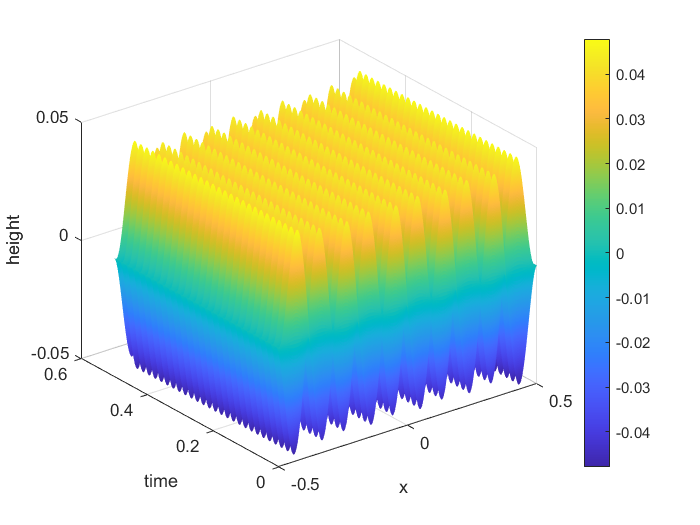


u_plot(t,x);

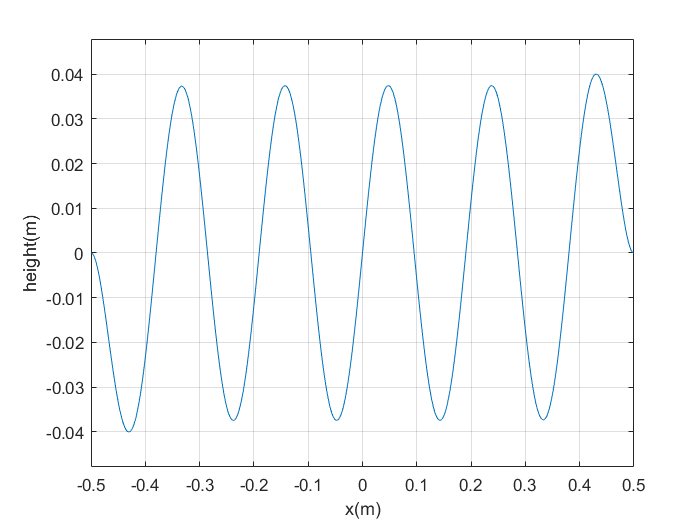

animate(x,x0,xn,t,t0,tn)

function fixed(x,t,source_pos,r)
    global u;
   
    w=300*pi;
    sp=0;
    for i=2:1:length(t)-2
        for j=3:1:length(x)-2
           
            u(i+1,j)=2*u(i,j)-u(i-1,j)-(u(i,j+2)-4*u(i,j+1)+6*u(i,j)-4*u(i,j-1)+u(i,j-2))*r;
            if(u(i+1,j)>100)
                disp(i+1);
                sp=1;
                break;
            end
        end
        u(i+1,source_pos)=1*sin(w*t(i));
%         if(i+1<36)
%             u(i+1,source_pos)=0.1*sin(w*t(i));
%         else
%             u(i+1,source_pos)=0;
%         end
        if(sp==1),break,end
       
        %disp(u(i,source_pos))
    end
end
function u_plot(t,x)
    global u
    figure;
    k=surf(x,t,u);
    set(k,'LineStyle','none')
    colorbar;
    xlabel('x')
    ylabel('time')
    zlabel('height')
end
function animate(x,x0,xn,t,t0,tn)
    global u
    figure
    hold on;
    for i = 1:5:5000
        plot(x,u(i,:));
        grid on;
        axis([x0 xn min(min(u)) max(max(u))]);
        xlabel('x(m)')
        ylabel('height(m)')
       
        pause(0.00000100);
        hold off;
    end
end
function eigenmode(t,x,r,mode,dx,a2)
    global u;
    FDM=1/(dx^4)*(diag(6+zeros(1,length(x)-4))+diag(-4+zeros(1,length(x)-5),1)+diag(-4+zeros(1,length(x)-5),-1)+diag(1+zeros(1,length(x)-6),2)+diag(1+zeros(1,length(x)-6),-2));
    [V,D]=eig(FDM);
    u(1,3:length(x)-2)=V(:,mode)';
    
    disp(sqrt(a2*D(mode,mode)));
    for i=2:1:length(t)
        for j=3:1:length(x)-2
            
            u(i,j)=u(1,j)*cos(sqrt(a2*D(mode,mode))*t(i));
        end
    end
    
    
end